# 2D Kalman Filter on OpenPose Data

**Initialization**

clear all;
close all ;
clc;
base_dir="data\";
cd(base_dir);

Video File & Keypoints

vid = VideoReader('vid_out_colab.avi')

vid =   VideoReader with properties:

   General Properties:
            Name: 'vid_out_colab.avi'
            Path: 'C:\Users\Clarisse Alago\Documents\MATLAB\gait-analysis\pre-processing\matlab\data'
        Duration: 4.5000
     CurrentTime: 0
       NumFrames: 135

   Video Properties:
           Width: 960
          Height: 540
       FrameRate: 30
    BitsPerPixel: 3
     VideoFormat: 'RGB24'


%raw_vid = VideoReader('vid_out.avi')
all_keypoints= readtable('keypoints_colab_fixed2.csv');


% specifying keypoint of interest
keypoint=[all_keypoints.l_ankle_x all_keypoints.l_ankle_y];

%We will de-normalize openpose measurements
keypoint=[keypoint(:,1)*vid.Width keypoint(:,2)*vid.Height];


Defining Variables

dt = 0.04; % sampling rate
frame_start = 10; % starting frame
u = 10; % !!! input/acceleration magnitude  !!!Important
Z=[keypoint(frame_start,1);keypoint(frame_start,2);-100;5]; %initialized state [pos_x, pos_y, v_x,v_y]
X_estimate= Z; % estimate of the initial location
process_noise= 5; % !!! if high we expect a lot of jumping around the variability in how fast the object is speeding up (stdv of acceleration: meters/sec^2) !!!
noise_x = 2.5; % !! measurement confidentiality measurement noise in x axis
noise_y = 2.5; % measurement noise in y axis

Defining Matrices

% Measurement Noise Covariance Matrix
R = [noise_x 0; 0 noise_y]; 

% Process noise matrix
Q = [dt^4/4 0 dt^3/2 0; ...
    0 dt^4/4 0 dt^3/2; ...
    dt^3/2 0 dt^2 0; ...
    0 dt^3/2 0 dt^2].*process_noise^2;

% Initial estimate for Variance
P = Q;

% State transition matrix
F = [1 0 dt 0; 0 1 0 dt; 0 0 1 0; 0 0 0 1];

% Control Matrix
G = [(dt^2/2); (dt^2/2); dt; dt];

% Observation Matrix
H = [1 0 0 0; 0 1 0 0 ];

Initializing result variables

%actual variables ?
OP= [];

Initilizing estimation variables

pos_all_estimate=[];
v_all_estimate =[];
P_estimate = P;
predict_state = [];
predict_var =[];

%circle stuff / may not be needed
r = 5; % r is the radius of the plotting circle
j=0:.01:2*pi; %to make the plotting circle

**Kalman Filtering**

looping through the frames

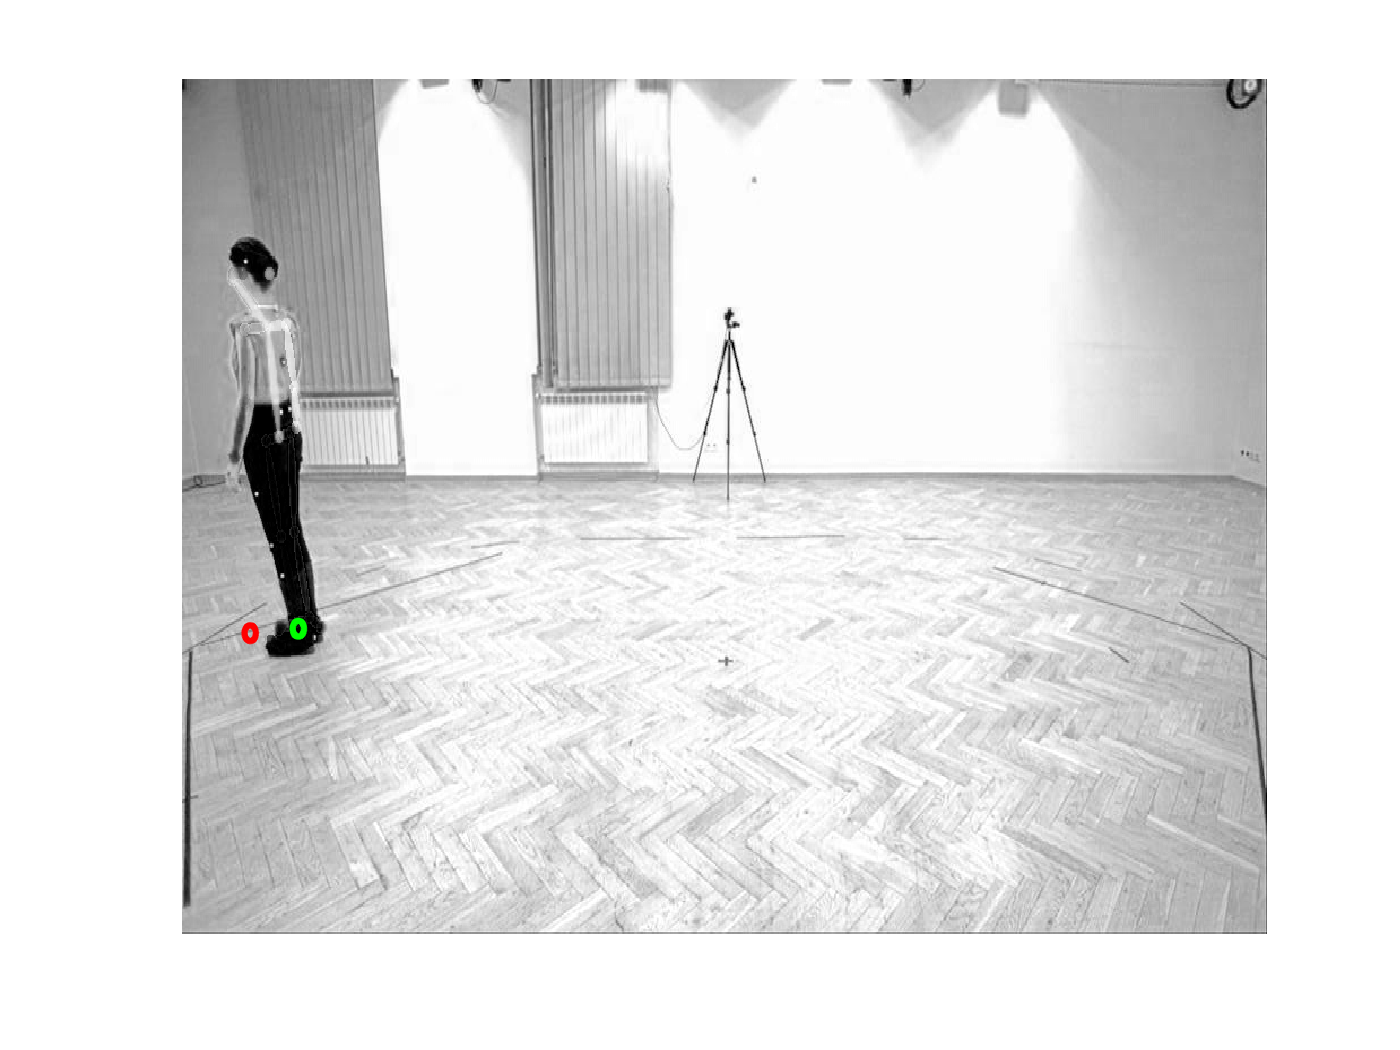

for n =frame_start:vid.numFrames
    
    % loading frame
    videoFrame = read(vid,n);
    img = videoFrame(:,:,1);
    
    % OpenPose Measurement
    OP(:,n)= [keypoint(n,1); keypoint(n,2)];
    
    
    %% KALMAN PREDICT %%
    %state
    X_estimate = F * X_estimate + G * u;
    predict_state = [predict_state;X_estimate(1)]; % ?
    
    %covariance
    P = F * P * F' + Q;
    predict_var = [ predict_var; P]; % ?
    
    %% KALMAN UPDATE %%
    %kalman gain
    K = P * H' * inv(H * P * H' + R);
    
    %state update
    X_estimate = X_estimate + K * (OP(:,n) - H * X_estimate);
    
    %covariance update
    P = (eye(4) - K*H)*P;
    
    
    % storing data
    pos_all_estimate = [pos_all_estimate; transpose(X_estimate(1:2))];
    v_all_estimate = [v_all_estimate; transpose(X_estimate(3:4))];
    
    % plotting image
    imagesc(img);
    axis off
    colormap(gray);
    hold on;
    plot(r*sin(j)+OP(1,n),r*cos(j)+OP(2,n),'.g'); % the actual tracking
    plot(r*sin(j)+X_estimate(1),r*cos(j)+X_estimate(2),'.r'); % the kalman filtered tracking
    hold off
    pause(0.1)
   
    % just for trial at n=1
    %break
end

Plotting Results

pos_all_estimate

pos_all_estimate =   872.7091  339.0990
  868.7324  339.3233
  864.7699  339.5646
  860.8121  339.8264
  856.8296  340.1118
  852.7947  340.4261
  848.6679  340.7700
  844.3953  341.1457
  839.9100  341.5555
  835.1794  342.0014


v_all_estimate

v_all_estimate =   -99.5949    5.3997
  -99.2057    5.8028
  -98.8275    6.2146
  -98.5241    6.6539
  -98.4357    7.1249
  -98.6039    7.6396
  -99.1013    8.1826
 -100.0258    8.7513
 -101.4794    9.3463
 -103.4057    9.9654


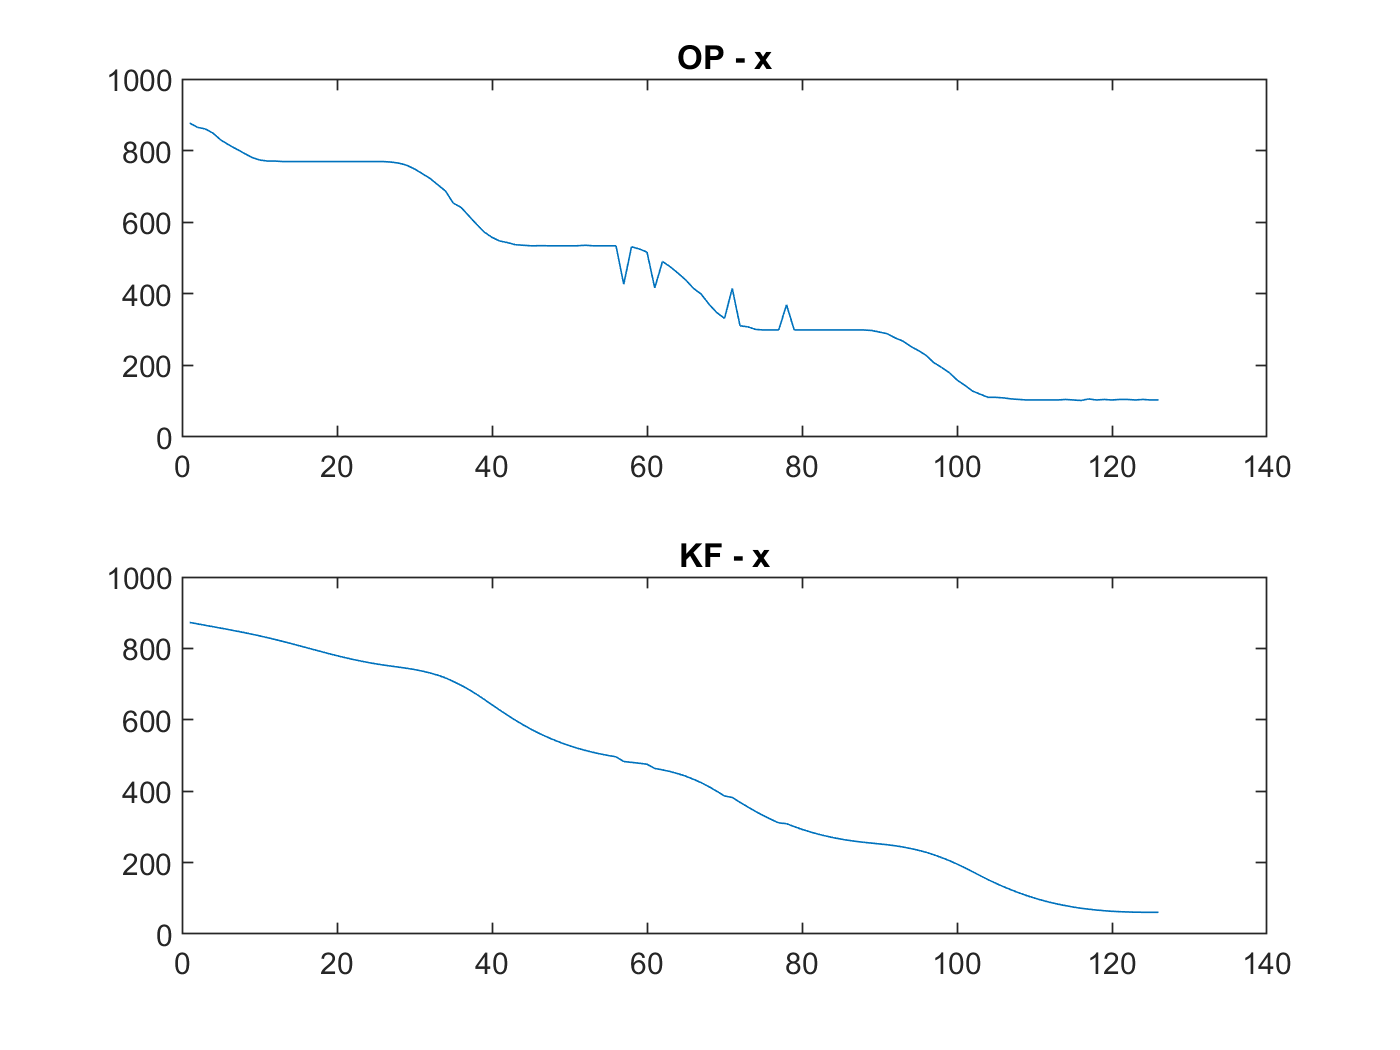


% X- coordinates
figure;
subplot(2,1,1)
plot(keypoint(frame_start:end,1))
title("OP - x")

subplot(2,1,2)
plot(pos_all_estimate(:,1))
title("KF - x")

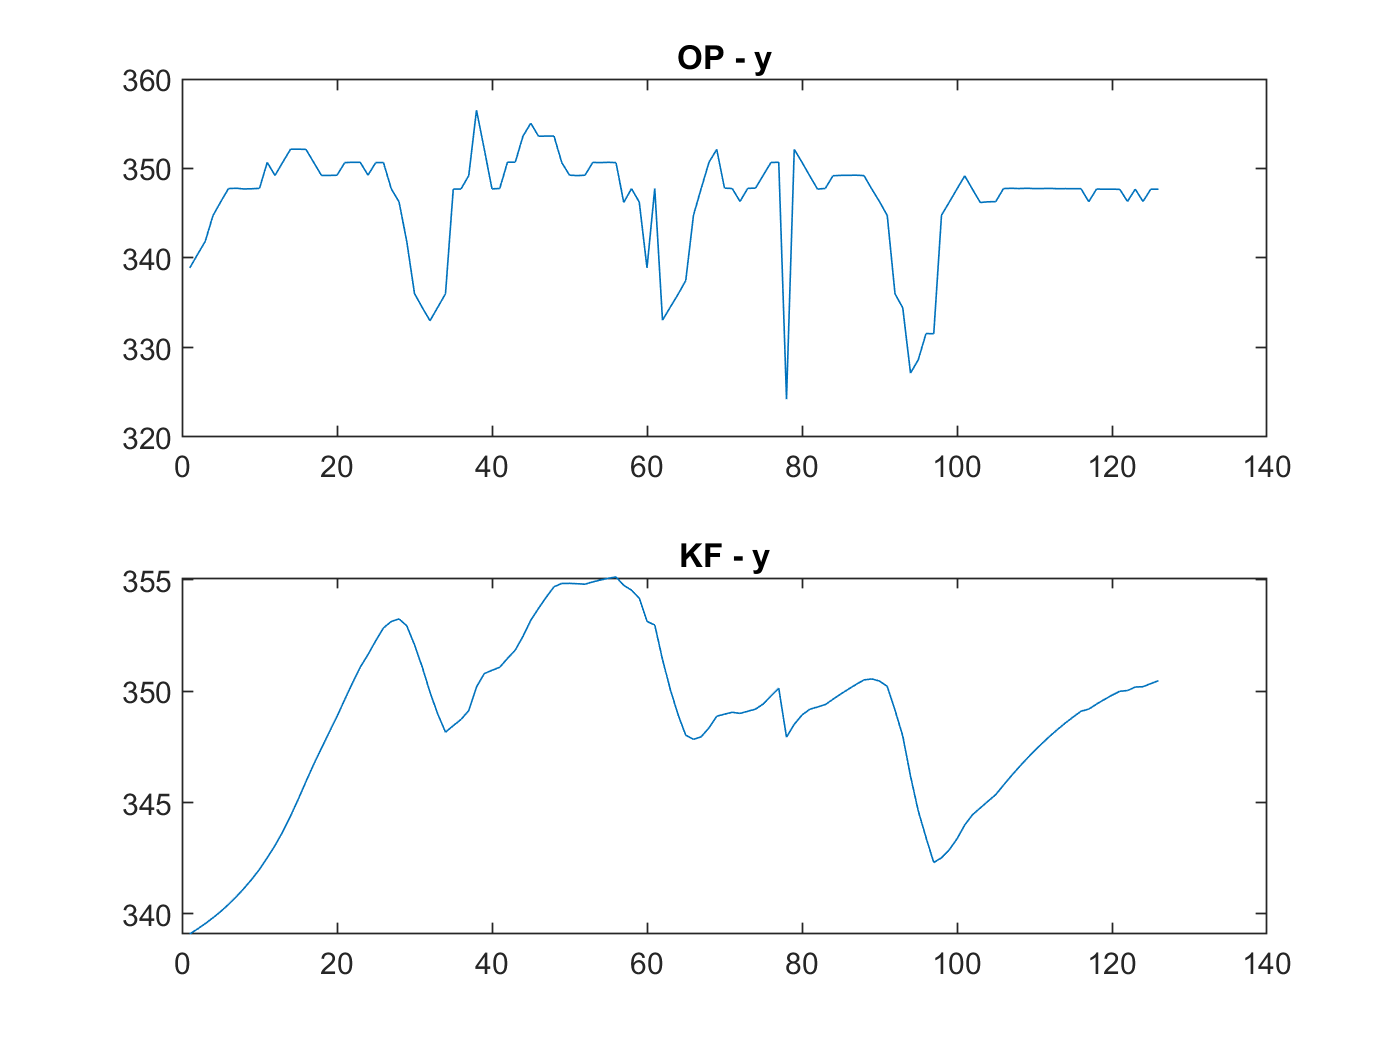


% Y- coordinates
figure;
subplot(2,1,1)
plot(keypoint(frame_start:end,2))
title("OP - y")

subplot(2,1,2)
plot(pos_all_estimate(:,2))
title("KF - y")




size(img)

ans =    540   960



% imagesc(img);
% hold on
% plot(keypoint(:,1), keypoint(:,2))
% plot(pos_all_estimate(:,1),pos_all_estimate(:,2))
% hold off

plot check

n=70

n = 70

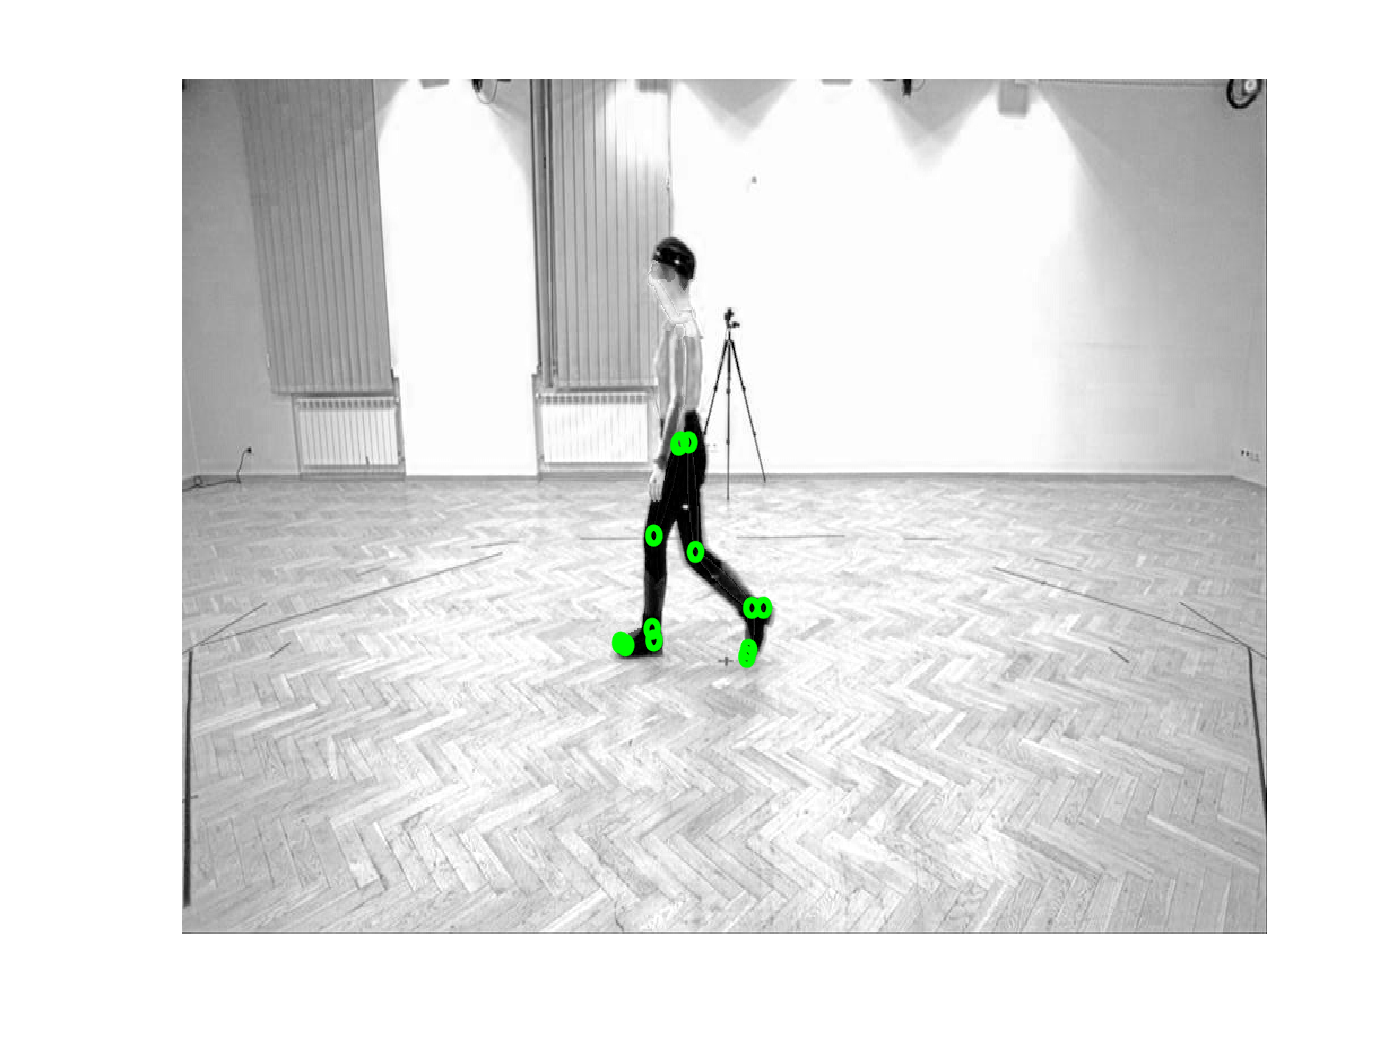

videoFrame = read(vid,n);
    img = videoFrame(:,:,1);
 %figure;
%imagesc(img);
    axis off
    colormap(gray);
    %hold on;
% specifying keypoint of interest
keypoint=[all_keypoints.l_smalltoe_x all_keypoints.l_smalltoe_y];

%We will de-normalize openpose measurements
keypoint=[keypoint(:,1)*vid.Width keypoint(:,2)*vid.Height];

OP(:,n)= [keypoint(n,1); keypoint(n,2)];
plot(r*sin(j)+OP(1,n),r*cos(j)+OP(2,n),'.g');